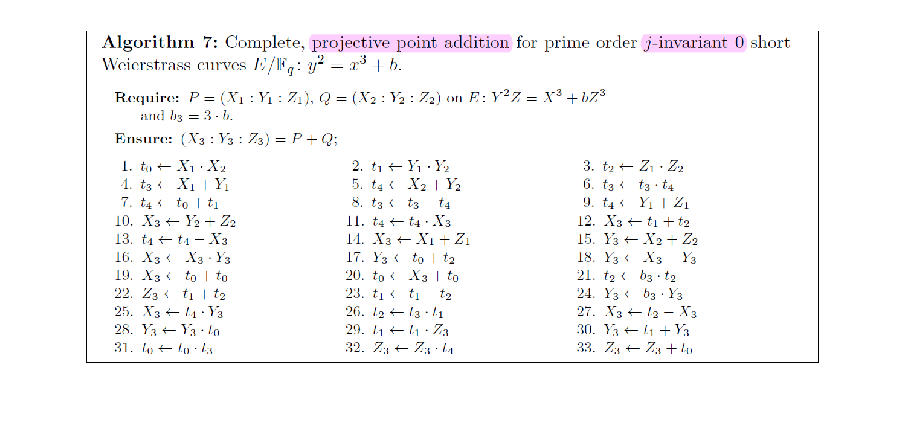

%----------------------------------------------------------------------
%-- Author: Poncha Joel
%--
%-- Project Name: Point Addition in Eliptic curve cryptography
%-- Module Name: projective point addition.
%-- Description: This is a matlab implementation of the Compleate projective point addition for prime order a=0
% short Weistrass curve y^2 = x^3 + b. The equations are proposed in this
% work "Complete addition formulas for prime order elliptic curves"  https://eprint.iacr.org/2015/1060.pdf
%----------------------------------------------------------------------
% Remark: Use this website to select curve and points and verify the
% addition results in this matlab program
% (https://andrea.corbellini.name/ecc/interactive/modk-add.html).
% This site can validate addition for big numbers: http://www.christelbach.com/eccalculator.aspx

imshow(imread("point_addition_equations.png"))

% b = 3;
% primeP =7;
% %(2,2,1) + (2, 2, 1) = (5, 3, 1)
% X1 = 2; Y1 = 2; Z1 = 1;
%%==============================================================
% b=2;
% primeP = 7;
% %(3,1,1) + (3,1,1) = (3,6,1)
% X1 = 3; Y1 = 1; Z1 = 1;
%%==============================================================
% b=4;
% primeP = 7;
% %(0,2,1) + (0,2,1) = (0,5,1)
% X1 = 0; Y1 = 2; Z1 = 1;
%%==============================================================
%% FOR SECP256K1
b=7;
primeP='115792089237316195423570985008687907853269984665640564039457584007908834671663';
X1='55066263022277343669578718895168534326250603453777594175500187360389116729240';
Y1='32670510020758816978083085130507043184471273380659243275938904335757337482424';
Z1=1;
%X3=89565891926547004231252920425935692360644145829622209833684329913297188986597;
%Y3=12158399299693830322967808612713398636155367887041628176798871954788371653930;
%(X1,Y1,1) + (X2,Y2,1) = (X3,Y3,1)

X2=X1; Y2=Y1; Z2=Z1;
B3=b*3;
[X3, Y3, Z3] = projective_point_addition(X1,Y1,Z1, X2,Y2,Z2, B3, primeP)

X3 =
    110383685576993659245168857245613307344564578195757623090394588386385391034312
Y3 =
    39155707150128334349216371677407456506802956851096117747929288260567018884059
Z3 =
    112386024462437979217642839804619380985487717678471186887195924032703633398313
